%Ben
load class10_record.mat %load data
[data] = Class10_Ben(500);

%CB
load class10_record.mat %load data
[f,a,Parseval] = spectrumCB_demo(class10_record.time, class10_record.data, 500);

%Okun
load class10_record.mat %load data
[fft_amplitude,frequency_vector] = Okun_Lecture10(class10_record.data,class10_record.time,32);

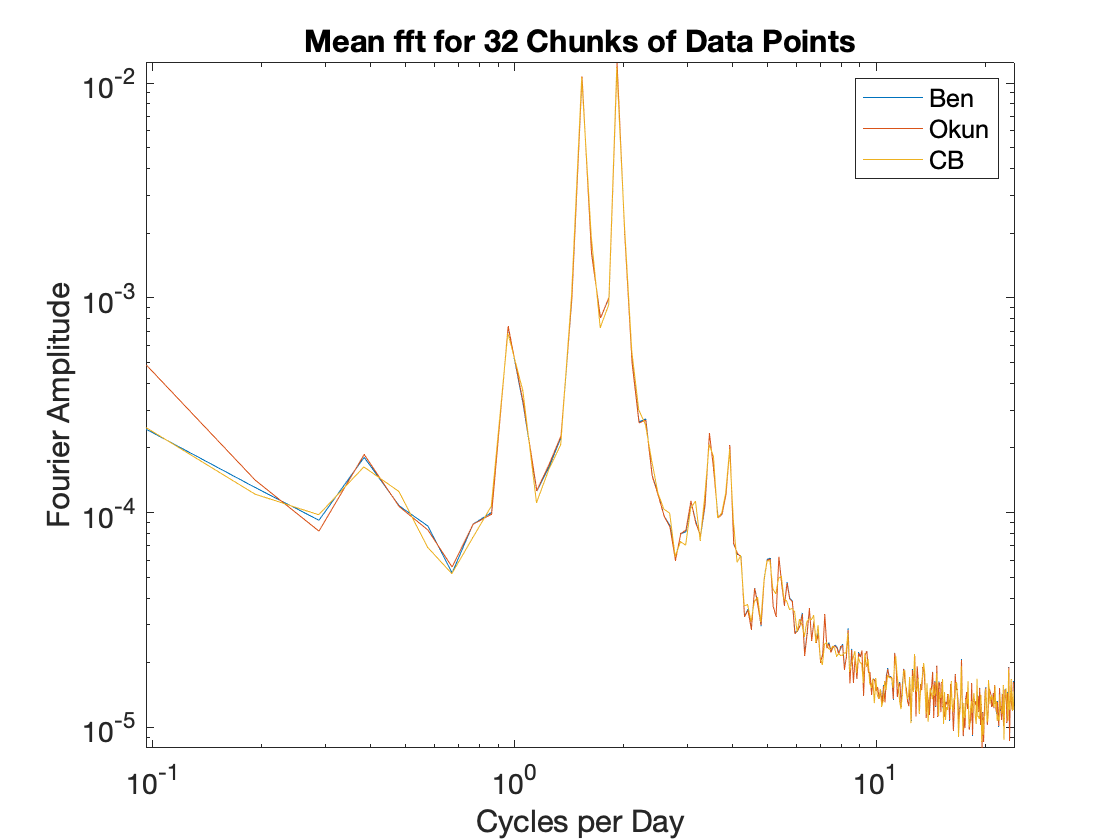

figure(1)
clf

loglog(data.f_vector,data.spectra)%Ben
hold on
loglog(frequency_vector,fft_amplitude)%Okun
loglog(f,a)%CB

legend('Ben','Okun','CB')
xlabel('Cycles per Day')
ylabel('Fourier Amplitude')
title('Mean fft for 32 Chunks of Data Points')

Final Project Ideas: